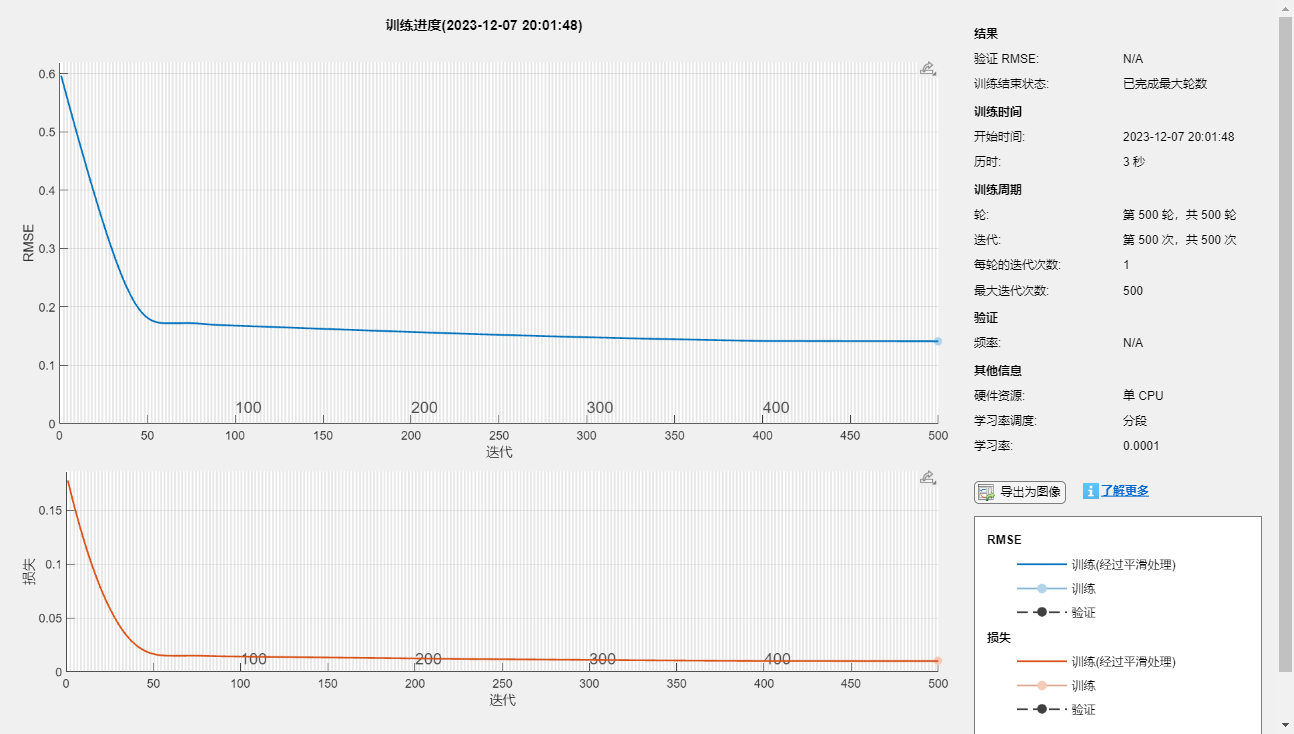

%%  清空环境变量
warning off             % 关闭报警信息
close all               % 关闭开启的图窗
clear                   % 清空变量
clc                     % 清空命令行
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  导入数据
result = xlsread('y.xls');
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据分析
num_samples = length(result);  % 样本个数
or_dim = size(result, 2);      % 原始特征+输出数目
kim = 13;                      % 延时步长（kim个历史数据作为自变量）
zim =  1;                      % 跨zim个时间点进行预测
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  划分数据集
for i = 1: num_samples - kim - zim + 1
    res(i, :) = [reshape(result(i: i + kim - 1, :), 1, kim * or_dim), result(i + kim + zim - 1, :)];
end
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据集分析
outdim = 1;                                  % 最后一列为输出
num_size = 1-(12/(119-kim));                    % 训练集占数据集比例
num_train_s = round(num_size * (num_samples-kim)); % 训练集样本个数
f_ = size(res, 2) - outdim;                  % 输入特征维度
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  划分训练集和测试集
P_train = res(1: num_train_s, 1: f_)';
T_train = res(1: num_train_s, f_ + 1: end)';
M = size(P_train, 2);
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
P_test = res(num_train_s + 1: end, 1: f_)';
T_test = res(num_train_s + 1: end, f_ + 1: end)';
N = size(P_test, 2);
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据归一化
[P_train, ps_input] = mapminmax(P_train, 0, 1);
P_test = mapminmax('apply', P_test, ps_input);

[t_train, ps_output] = mapminmax(T_train, 0, 1);
t_test = mapminmax('apply', T_test, ps_output);
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据平铺
%   将数据平铺成1维数据只是一种处理方式
%   也可以平铺成2维数据，以及3维数据，需要修改对应模型结构
%   但是应该始终和输入层数据结构保持一致
P_train =  double(reshape(P_train, f_, 1, 1, M));
P_test  =  double(reshape(P_test , f_, 1, 1, N));

t_train = t_train';
t_test  = t_test' ;
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据格式转换
for i = 1 : M
    p_train{i, 1} = P_train(:, :, 1, i);
end

for i = 1 : N
    p_test{i, 1}  = P_test( :, :, 1, i);
end
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  创建模型
layers = [
    sequenceInputLayer(f_)                % 建立输入层
    
    bilstmLayer(10, 'OutputMode', 'last') % BiLSTM层
    
    fullyConnectedLayer(outdim)           % 全连接层
    regressionLayer];                     % 回归层
%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------- 
%%  参数设置
options = trainingOptions('adam', ...      % Adam 梯度下降算法
    'MaxEpochs', 500, ...                  % 最大迭代次数 400
    'MiniBatchSize', 128, ...              % 批量大小 
    'InitialLearnRate', 1e-3, ...          % 初始学习率为0.001
    'LearnRateSchedule', 'piecewise', ...  % 学习率下降
    'LearnRateDropFactor', 0.1, ...        % 学习率下降因子 0.1
    'LearnRateDropPeriod', 400, ...        % 经过 400 次训练后 学习率为 0.001 * 0.1
    'Shuffle', 'every-epoch', ...          % 打乱数据集
    'Plots', 'training-progress', ...      % 画出曲线
    'Verbose', false);
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  训练模型
net = trainNetwork(p_train, t_train, layers, options);

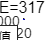


%%  仿真预测
t_sim1 = predict(net, p_train);
t_sim2 = predict(net, p_test );
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  数据反归一化
T_sim1 = mapminmax('reverse', t_sim1, ps_output);
T_sim2 = mapminmax('reverse', t_sim2, ps_output);

%%  均方根误差
error1 = sqrt(sum((T_sim1' - T_train).^2) ./ M);
error2 = sqrt(sum((T_sim2' - T_test ).^2) ./ N);

%%  查看网络结构
analyzeNetwork(net)
%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  绘图
figure
plot(1: M, T_train, 'r-', 1: M, T_sim1, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本')
ylabel('预测结果')
string = {'训练集预测结果对比'; ['RMSE=' num2str(error1)]};
title(string)
xlim([1, M])
grid

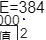

%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
figure
plot(1: N, T_test, 'r-', 1: N, T_sim2, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本')
ylabel('预测结果')
string = {'测试集预测结果对比'; ['RMSE=' num2str(error2)]};
title(string)
xlim([1, N])
grid

%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%%  相关指标计算
%  R2
R1 = 1 - norm(T_train - T_sim1')^2 / norm(T_train - mean(T_train))^2;
R2 = 1 - norm(T_test  - T_sim2')^2 / norm(T_test  - mean(T_test ))^2;

disp(['训练集数据的R2为：', num2str(R1)])

训练集数据的R2为：0.42229


disp(['测试集数据的R2为：', num2str(R2)])

测试集数据的R2为：0.060444


%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%  MAE
mae1 = sum(abs(T_sim1' - T_train)) ./ M ;
mae2 = sum(abs(T_sim2' - T_test )) ./ N ;

disp(['训练集数据的MAE为：', num2str(mae1)])

训练集数据的MAE为：235.922


disp(['测试集数据的MAE为：', num2str(mae2)])

测试集数据的MAE为：273.2755


%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%  MBE
mbe1 = sum(T_sim1' - T_train) ./ M ;
mbe2 = sum(T_sim2' - T_test ) ./ N ;

disp(['训练集数据的MBE为：', num2str(mbe1)])

训练集数据的MBE为：1.6324


disp(['测试集数据的MBE为：', num2str(mbe2)])

测试集数据的MBE为：84.6294
